**Weight Loss dataset**

This data was collected from a crowd-sourced experiment looking at the effects of various parameters on weight loss. Data was gathered either through the use of self-tracking apps (such as activity trackers like FitBit (TM)) or through questionnaires The study lasted 3 months and the values presented here have been aggregated and patients with missing data have been dropped along with any potentially identifiable information. Our overall goal is to find which parameters are most associated with weight loss.

**Data Description:** The data is given in a sqlite database named **weightdata.sqlite**, with a single table, **patient**. * age: Patient's age at the start of the study. * gender: Self-identified gender. * height: The patient's height (in inches). * initweight: The weight of the patient at the start of the study (in pounds). * calintake: The average number of calories consumed per day. * jobstatus: The self-identified job status, either Active or Inactive. * timecardio: The average minutes of cardio (per week). * timeresist: The average minutes of resistance training (per week). * sleep: The average amount of sleep (hours) per day. * steps: The average number of steps per day (counted using phone accelerometers). * deltaweight: The change in weight after the 3-month study (in pounds).

**Variable names**

- d: Database connection.

- data: All patient data, represented as a Matlab table object.

**Objectives:**

- Understand the dataset

- Be able to manipulate the database tables in the DB Browser for SQlite

- Connection to the database using Matlab functions, native connection, and JDBC

- Use SQL query in Matlab, import data to a cell array, convert a cell array to a table, and convert to a cell array to a matrix

- Be able to manipulate the data in a cell array, table, and matrix

- Logical index

- Corrcoef function corrcoef() [https://www.mathworks.com/help/matlab/ref/corrcoef.html#bunkanr](https://www.mathworks.com/help/matlab/ref/corrcoef.html#bunkanr)

- Two-sample t-test - MATLAB ttest2 [`[h,p,ci,stats] = ttest2(``___``)`](https://www.mathworks.com/help/stats/ttest2.html#d117e865369)

- Combine variables to test a new model

- Multivariate linear regression, mvregress() 

- Z-scaling

%function hw3_primer

## Weight Loss dataset

change to false if you need to skip the database functions and want to work on the plotting & statistics.

USEDB=true;

if USEDB
end
    

## Connect to the database

dbfile = fullfile(pwd,'weightdata.sqlite');
% native sqlite connection
conn = sqlite(dbfile)

conn =   sqlite with properties:

      Database: 'C:\Users\kabil\OneDrive - Drexel University\Academic\3 - Pre-Junior\1 - Fall Quarter\BMES 375\bmes375.TonyOkeke.tko35\HW5\weightdata.sqlite'
        IsOpen: 1
    IsReadOnly: 0

## How many patients do not exercise(cardio and resist are zero)?  Query returns a cell array.

% Let's get all the data for patients that don't exercise (these patients have
% timecardio AND timeresist of zero. The count will then just be the
% number of elements in the structure array.
sqlquery='SELECT * FROM patient WHERE timecardio=0 AND timeresist=0';
allmissing= fetch(conn,sqlquery)

allmissing = 48×12 cell array
    {[ 7]}    {[21]}    {'Female'}    {[60.6551]}    {[153.3522]}    {[      1500]}    {'Active'  }    {[0]}    {[0]}    {[6.7495]}    {[4.2827e+03]}    {[ 3.9968]}
    {[16]}    {[39]}    {'Female'}    {[57.7803]}    {[133.4423]}    {[      1500]}    {'Active'  }    {[0]}    {[0]}    {[7.0986]}    {[4.4624e+03]}    {[10.0285]}
    {[18]}    {[24]}    {'Male'  }    {[69.1721]}    {[177.2989]}    {[      1500]}    {'Active'  }    {[0]}    {[0]}    {[7.4845]}    {[3.4461e+03]}    {[-2.5926]}
    {[19]}    {[41]}    {'Male'  }    {[77.9292]}    {[174.8174]}    {[      1500]}    {'Active'  }    {[0]}    {[0]}    {[8.9922]}    {[4.3349e+03]}    {[ 0.9817]}
    {[28]}    {[41]}    {'Male'  }    {[72.4046]}    {[196.5634]}    {[      1500]}    {'Active'  }    {[0]}    {[0]}    {[9.1250]}    {[3.6975e+03]}    {[-0.4721]}
    {[33]}    {[47]}    {'Female'}    {[66.2543]}    {[161.1063]}    {[2.0790e+03]}    {'Inactive'}    {[0]}    {[0]}    {[6.1339]}    {[2.8474e+

sqlquery='SELECT id FROM patient WHERE timecardio=0 AND timeresist=0';
allmissing= numel(fetch(conn,sqlquery))

allmissing = 48

Relying on Matlab's display of variable values is okay for debugging, but not a good general practice. Use fprintf to tell what the number represents.

fprintf('%d of the patients do not exercise.\n', allmissing);

48 of the patients do not exercise.


## What are the average ages for male and female patients?

Get all male data, and find their average age.

sqlquery='SELECT * FROM patient WHERE gender="Male"';
allmaledata = fetch(conn,sqlquery)

allmaledata = 122×12 cell array
    {[  6]}    {[38]}    {'Male'}    {[62.5520]}    {[187.9075]}    {[1.7481e+03]}    {'Inactive'}    {[15.2110]}    {[38.4704]}    {[ 7.6166]}    {[3.5263e+03]}    {[ -3.3444]}
    {[  9]}    {[44]}    {'Male'}    {[75.5218]}    {[222.2269]}    {[1.8750e+03]}    {'Inactive'}    {[14.6797]}    {[35.4773]}    {[ 6.4738]}    {[2.5459e+03]}    {[ -0.2475]}
    {[ 11]}    {[44]}    {'Male'}    {[73.5189]}    {[179.1951]}    {[1.7726e+03]}    {'Inactive'}    {[17.2165]}    {[43.8691]}    {[ 8.7945]}    {[3.5160e+03]}    {[ -7.3085]}
    {[ 12]}    {[38]}    {'Male'}    {[55.3979]}    {[213.1399]}    {[1.7168e+03]}    {'Inactive'}    {[ 8.4671]}    {[45.4156]}    {[ 5.5618]}    {[2.1507e+03]}    {[ -3.6050]}
    {[ 14]}    {[23]}    {'Male'}    {[65.4305]}    {[185.0747]}    {[1.8586e+03]}    {'Inactive'}    {[17.2012]}    {[27.3142]}    {[ 9.1738]}    {[3.1406e+03]}    {[  0.2718]}
    {[ 18]}    {[24]}    {'Male'}    {[69.1721]}    {[177.2989]}    {[      15

Select just age

sqlquery='SELECT age FROM patient WHERE gender="Male"';
allmaleages = fetch(conn,sqlquery)

allmaleages = 122×1 cell array
    {[38]}
    {[44]}
    {[44]}
    {[38]}
    {[23]}
    {[24]}
    {[41]}
    {[22]}
    {[34]}
    {[39]}
    {[29]}
    {[41]}
    {[26]}
    {[36]}
    {[18]}
    {[21]}
    {[36]}
    {[21]}
    {[21]}
    {[43]}
    {[39]}
    {[45]}
    {[23]}
    {[24]}
    {[29]}
    {[44]}
    {[43]}
    {[28]}
    {[29]}
    {[33]}
    {[37]}
    {[38]}
    {[32]}
    {[39]}
    {[29]}
    {[44]}
    {[31]}
    {[32]}
    {[32]}
    {[33]}
    {[32]}
    {[47]}
    {[46]}
    {[37]}
    {[20]}
    {[26]}
    {[30]}
    {[29]}
    {[20]}
    {[26]}
    {[33]}
    {[44]}
    {[19]}
    {[46]}
    {[24]}
    {[22]}
    {[35]}
    {[35]}
    {[33]}
    {[39]}
    {[47]}
    {[21]}
    {[21]}
    {[33]}
    {[38]}
    {[34]}
    {[45]}
    {[41]}
    {[41]}
    {[41]}
    {[37]}
    {[48]}
    {[39]}
    {[41]}
    {[19]}
    {[41]}
    {[36]}
    {[39]}
    {[18]}
    {[33]}
    {[29]}
    {[47]}
    {[31]}
    {[24]}
    {[28]}
    {[24]}
    {[21]}
    {[34]}
 

Extract the age into a vector, and calculate the average.

allmaleage = cell2mat(allmaleages);

avgmaleage = mean(allmaleage)

avgmaleage = 33.2623

fetch(conn, 'SELECT gender, AVG(age) FROM patient GROUP BY gender')

ans = 2×2 cell array
    {'Female'}    {[32.6641]}
    {'Male'  }    {[33.2623]}

We can let SQL group the patients and calculate average for each group.

avgagedata = fetch(conn, 'SELECT gender, AVG(age) AS avgage FROM patient GROUP BY gender');
disp(avgagedata)

    'Female'    [32.6641]
    'Male'      [33.2623]



## Working with the data as a table

% Let's read the entire database table into a Matlab cell array.
sqlquery='SELECT * FROM patient'

sqlquery = 'SELECT * FROM patient'

data = fetch(conn,sqlquery)

data = 250×12 cell array
    {[ 1]}    {[19]}    {'Female'}    {[59.3734]}    {[137.1087]}    {[1.9678e+03]}    {'Inactive'}    {[39.1656]}    {[ 3.5163]}    {[9.0446]}    {[3.3119e+03]}    {[ 0.1447]}
    {[ 2]}    {[19]}    {'Female'}    {[82.6719]}    {[154.9608]}    {[1.8850e+03]}    {'Inactive'}    {[37.6153]}    {[ 1.2296]}    {[8.7172]}    {[3.6939e+03]}    {[ 8.1381]}
    {[ 3]}    {[37]}    {'Female'}    {[61.0149]}    {[132.0130]}    {[      1500]}    {'Active'  }    {[38.3226]}    {[ 0.4893]}    {[9.3964]}    {[3.1937e+03]}    {[-3.1881]}
    {[ 4]}    {[36]}    {'Female'}    {[62.4880]}    {[129.7659]}    {[1.7951e+03]}    {'Inactive'}    {[36.2942]}    {[ 9.0963]}    {[8.6012]}    {[2.9419e+03]}    {[ 2.4569]}
    {[ 5]}    {[32]}    {'Female'}    {[59.1823]}    {[132.2316]}    {[      1500]}    {'Active'  }    {[36.5790]}    {[ 0.6230]}    {[8.5469]}    {[3.6457e+03]}    {[ 0.6059]}
    {[ 6]}    {[38]}    {'Male'  }    {[62.5520]}    {[187.9075]}    {[1.7481e+03]}    {'I


% convert the cell array to a table

dbdata = cell2table (data,'VariableNames', {'id' 'age' 'gender' 'height' 'initweight' 'calintake' 'jobstatus' 'timecardio' 'timeresist' 'sleep' 'steps' 'deltaweight'})

dbdata = 250×12 table
    id    age      gender      height    initweight    calintake     jobstatus      timecardio    timeresist    sleep     steps     deltaweight
    __    ___    __________    ______    __________    _________    ____________    __________    __________    ______    ______    ___________
     1    19     {'Female'}    59.373      137.11       1967.8      {'Inactive'}      39.166        3.5163      9.0446    3311.9      0.14471  
     2    19     {'Female'}    82.672      154.96         1885      {'Inactive'}      37.615        1.2296      8.7172    3693.9       8.1

fetch(conn,sqlquery,'DataReturnFormat',"structure", ...
    'MaxRows',5)

Error using sqlite/fetch
Too many input arguments.

dbdata.height

ans =    59.3734
   82.6719
   61.0149
   62.4880
   59.1823
   62.5520
   60.6551
   69.7559
   75.5218
   62.5327


dbdata.age

ans = 250×1 int64 column vector
   19
   19
   37
   36
   32
   38
   21
   24
   44
   24


Let's find the average height of all patients

avgheight = mean(dbdata.height)

avgheight = 66.6122

Let's find the average height of female patients

I = strcmpi( dbdata.gender, 'Female');
%I column logical array 1x250

avgfemaleheight = mean( dbdata.height(I) )

avgfemaleheight = 64.8959

Boxplot of heights for each gender.

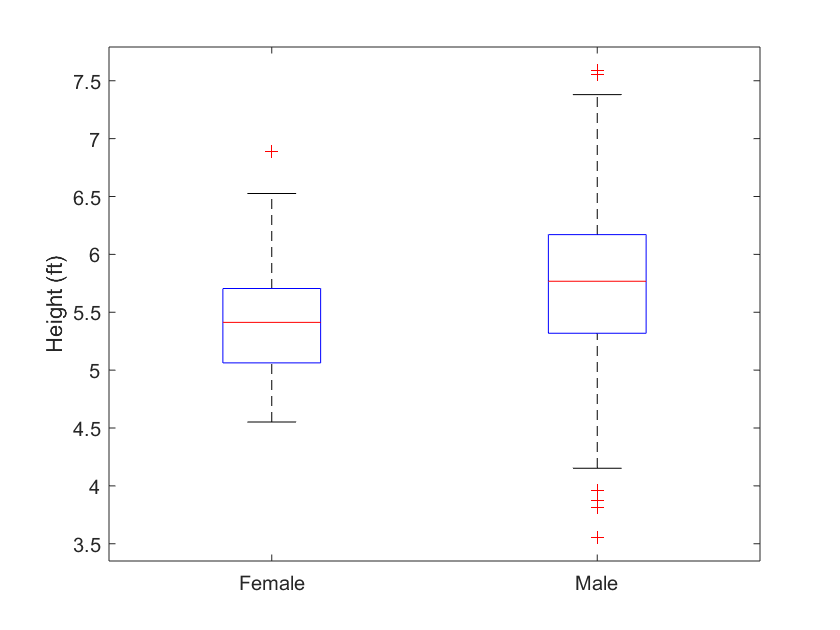

boxplot( dbdata.height/12, dbdata.gender ),  ylabel('Height (ft)')

## Is there a statistical difference between the heights of males and females?

[~,pvalue]=ttest2(dbdata.height(I), dbdata.height(~I)) % the default is at 95% confidence level. p value <0.05

pvalue = 2.6602e-04

if pvalue<=0.01
	fprintf('Yes, there is a statistical difference between the heights of males and females (p=%.1e)\n',pvalue);
else
	fprintf('No, there is no statistical difference between the heights of males and females (p=%.1e)\n',pvalue);
end

Yes, there is a statistical difference between the heights of males and females (p=2.7e-04)


Extract the age, height of the first five patients. First, as a new table

dbdata(1:5, {'age', 'height'})

ans = 5×2 table
    age    height
    ___    ______

    19     59.373
    19     82.672
    37     61.015
    36     62.488
    32     59.182


Now as a numeric matrix.

dbdata{1:5, {'age', 'height'}}

ans = 5×2 int64 matrix
   19   59
   19   83
   37   61
   36   62
   32   59


Create a new table just from the female data.

%femaledata = data( strcmp(data.gender,'Female'), data.Properties.VariableNames);
% In Matlab>2017a, we can now use ":"
femaledata = dbdata( strcmp(dbdata.gender,'Female'), :);

## gscatter(): Plotting with groups

Sometimes extra information can be inferred when plotting using the "color" dimension.

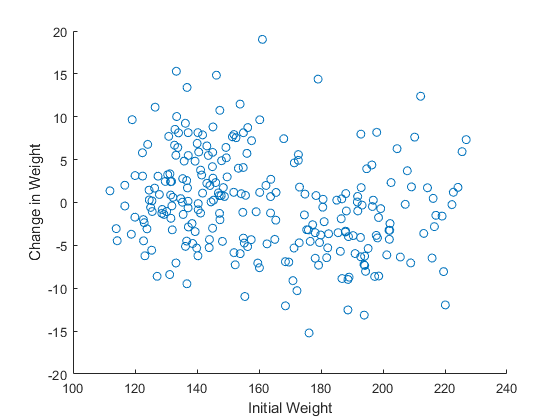


figure;

scatter(dbdata.initweight, dbdata.deltaweight), xlabel('Initial Weight'), ylabel('Change in Weight')

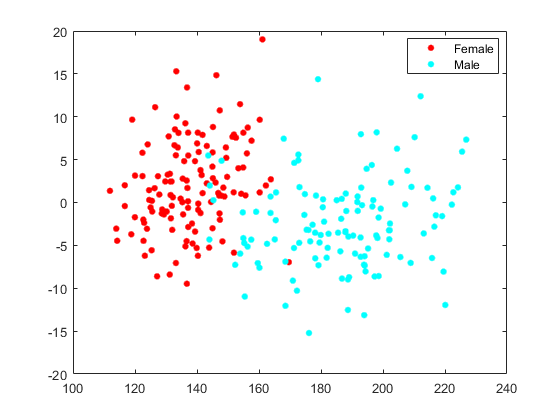

gscatter(dbdata.initweight, dbdata.deltaweight, dbdata.gender)

now let's show gender using color.

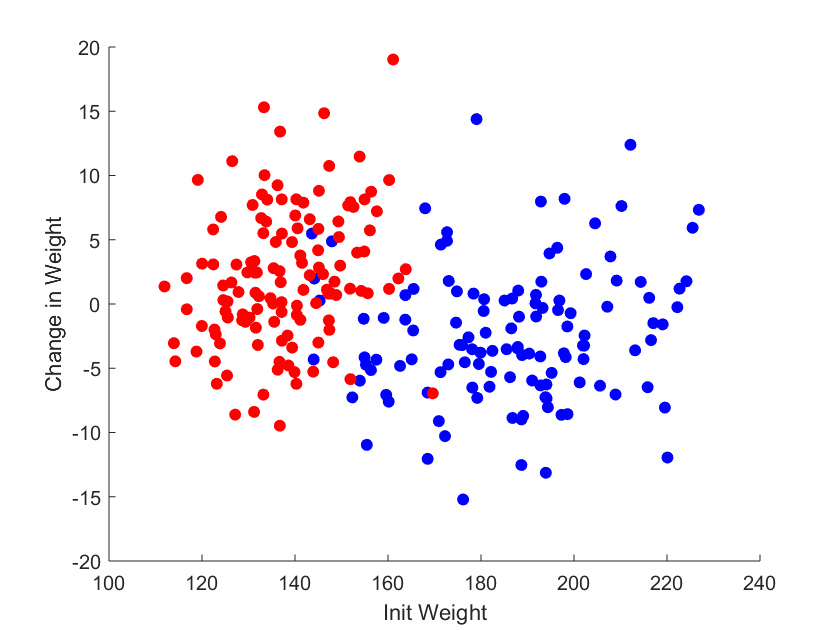

Imale = strcmp(dbdata.gender, 'Male');
clf, hold on
scatter(dbdata.initweight(Imale),  dbdata.deltaweight(Imale),  'b', 'filled')
scatter(dbdata.initweight(~Imale), dbdata.deltaweight(~Imale), 'r', 'filled')
hold off
xlabel('Init Weight'), ylabel('Change in Weight')

Matlab already has a function, gscatter() to do just that.

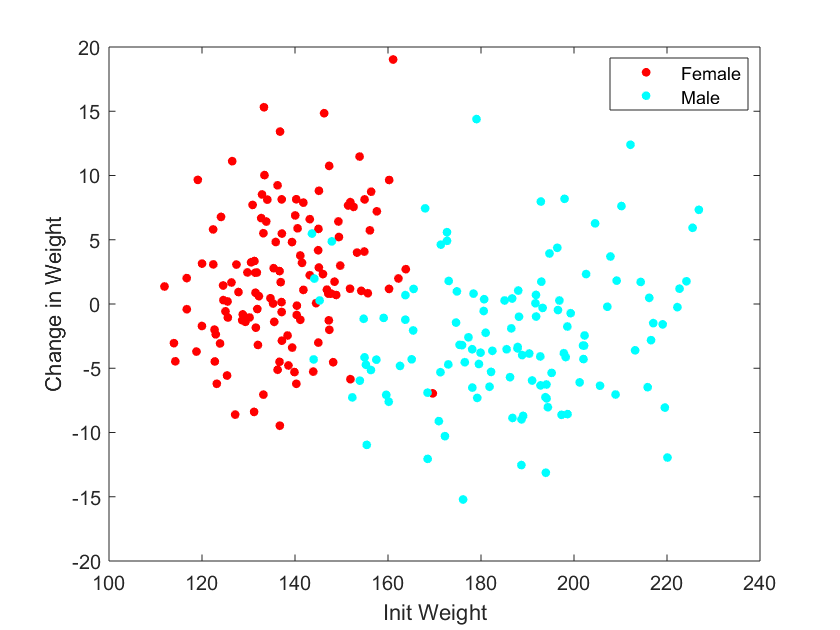

gscatter(dbdata.initweight, dbdata.deltaweight, dbdata.gender)
xlabel('Init Weight'), ylabel('Change in Weight')

## Statistical Analysis

Makes sense, men (blue) on average weigh more than women (red). Can we test to quantify whether this difference is due to chance?

% Null hypothesis: That mean of  the two groups are equal ... any difference
% observed is just due to the chance.
%[h,p,ci,stats]=ttest2(x,y,Name,Value)
%The result h is 1 if the test rejects the null hypothesis at the 5%  or 1% significance level, and 0 otherwise.

[h, pvalue, ci] = ttest2(dbdata.initweight(Imale), dbdata.initweight(~Imale), 'alpha', 0.01)

h = 1

pvalue = 1.4544e-64

ci =    42.9600
   53.7048


% Default alpha is 0.05, otherwise, you can define as you wish.  
% here we use 0.01, because of p<0.01 so, h is 1. 
% So, it is True, therefore we reject the hypothesis. Meaning that it is
% unlikely that the difference in mean is due to chance alone. The CI
% tells us that the difference in mean is between 43 and 54 lbs.

Back to the original plot. Let’s put a trend-line in.

trend = polyfit(dbdata.initweight, dbdata.deltaweight, 1)

trend =    -0.0461    7.3400


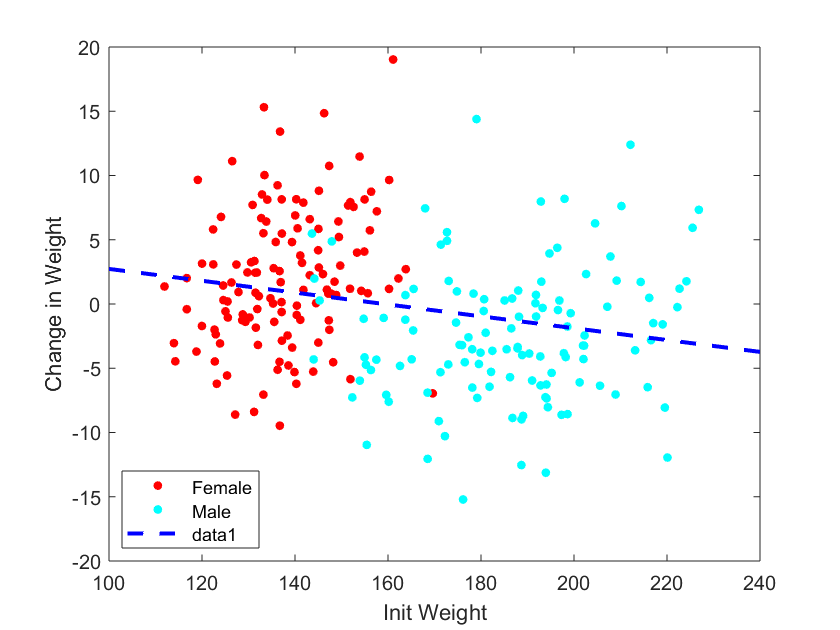

hold on
plot(xlim, (xlim)*trend(1) + trend(2), 'b--', 'linewidth', 2)
hold off

%TODO: use a function for polyfit & plot trend line. hint: isplot, xlim.

[dbdata.initweight, dbdata.deltaweight]

ans =   137.1087    0.1447
  154.9608    8.1381
  132.0130   -3.1881
  129.7659    2.4569
  132.2316    0.6059
  187.9075   -3.3444
  153.3522    3.9968
  131.2006   -8.4004
  222.2269   -0.2475
  144.5377    0.0674


## How much does this trendline explain the data? Here we'll use the correlation coefficient.

r(1,1)  is the comparison between data.initweigh and data.initweight;  r(1,2) data.initweigh and deltaweight; 

[r, p] =corrcoef( [dbdata.initweight, dbdata.deltaweight])

r =     1.0000   -0.2360
   -0.2360    1.0000


p =     1.0000    0.0002
    0.0002    1.0000



% This function tells us two things. 
%
% Due to Matlab implementation it takes
% the input as a matrix, and returns correlation of variables in each
% column. The result is a symmetric, square matrix; we want the 1,2
% position for correlation between 1st and 2nd columns.
% r is the correlation value (varies between -1 and 1. -1 means 100% reversely correlated, 
% increase/decrease.  1 means increase/increase)

% The r^2 value can be used as an estimate of the amount of variance in the dependent variable
% that's explained by the independent variable. The p-value measures the
% likelihood that the correlation is by chance.

r(1,2)

ans = -0.2360

r2 = r(1,2)^2 

r2 = 0.0557

h = p(1,2) < 0.05

h = logical
   1

% So in this case, yes, the Initial Weight is significantly correlated with
% the amount of weight loss, however, it only explains 5% of the variance
% we see.

The statistical tests supplement what is shown on the plot. Let's summarize the results now in the figure caption.

**Figure Caption:** The weight at intake  shows a weak negative correlation between intake weight and change in weight three months later. The intake weight (lbs) and change in weight (lbs) was plotted for males (blue) and females (red). While the slope is statistically significant (p<0.01) the R^2=0.056 implying that it has minimal predictive power.

## Multivariate regression

If you were to look at each of the patient parameters, you'd see that individually each only accounts for 5-10% of the observed variance in the deltaweight (not very predictive). However, if we combine them we can get better results.

% For this example I'm going to assume that the weight-loss is a function
% of initialweight, steps, minutes of resistance training, plus a constant term.

% First I need to put that data into a matrix. You'll notice that I include
% a constant field, this is IMPORTANT.
% ones(size(dbdata.timeresist)) -> all other factors
X = [dbdata.initweight, dbdata.steps, dbdata.timeresist, ones(size(dbdata.timeresist))]

X = 	1.0e+03 *

    0.1371    3.3119    0.0035    0.0010
    0.1550    3.6939    0.0012    0.0010
    0.1320    3.1937    0.0005    0.0010
    0.1298    2.9419    0.0091    0.0010
    0.1322    3.6457    0.0006    0.0010
    0.1879    3.5263    0.0385    0.0010
    0.1534    4.2827         0    0.0010
    0.1312    2.9950    0.0071    0.0010
    0.2222    2.5459    0.0355    0.0010
    0.1445    2.6167    0.0009    0.0010


y = dbdata.deltaweight

y =     0.1447
    8.1381
   -3.1881
    2.4569
    0.6059
   -3.3444
    3.9968
   -8.4004
   -0.2475
    0.0674


now we want to solve the linear equation y = Xw, where w is a set of weights that minimizes the least-squared difference between the predicted and observed values.

% w -> effect sizes
w = mvregress(X, y)

w =     0.0268
   -0.0007
   -0.1969
    1.5963


ypred = X*w;

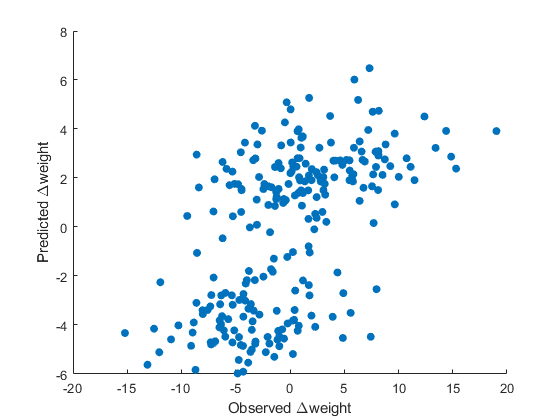


figure;
scatter(y, ypred, 'filled')
xlabel('Observed {\Delta}weight'), ylabel('Predicted {\Delta}weight')

Let's add a trendline

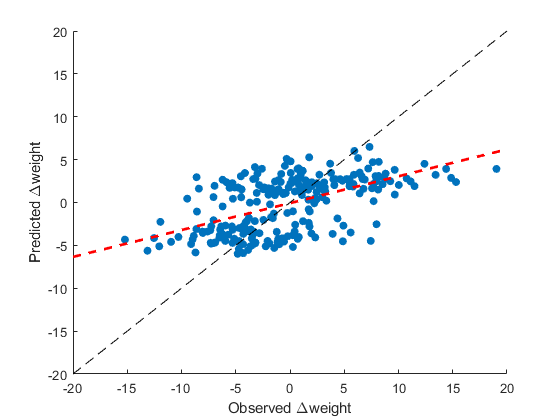

trend = polyfit(y, ypred, 1);
hold on
plot(-20:20, (-20:20)*trend(1)+trend(2), 'r--', 'linewidth', 2)
plot(-20:20, -20:20, 'k--')
hold off


[r, p] = corrcoef([y, ypred])

r =     1.0000    0.5600
    0.5600    1.0000


p =     1.0000    0.0000
    0.0000    1.0000



r2 = r(1,2)^2

r2 = 0.3136


h = p(1,2) < 0.01

h = logical
   1

**Figure Caption:** A linear model combining the initial weight, the daily number of steps, and daily minutes of resistance exercise predicts 30% of the variation. The predicted values based on the linear model were plotted versus the known values for the same patients. The red line shows the best-fit line with an R^2 = 0.31 and p<0.01.

## Effect Sizes

The coefficients from the multivariate regression represent the "effect sizes". 

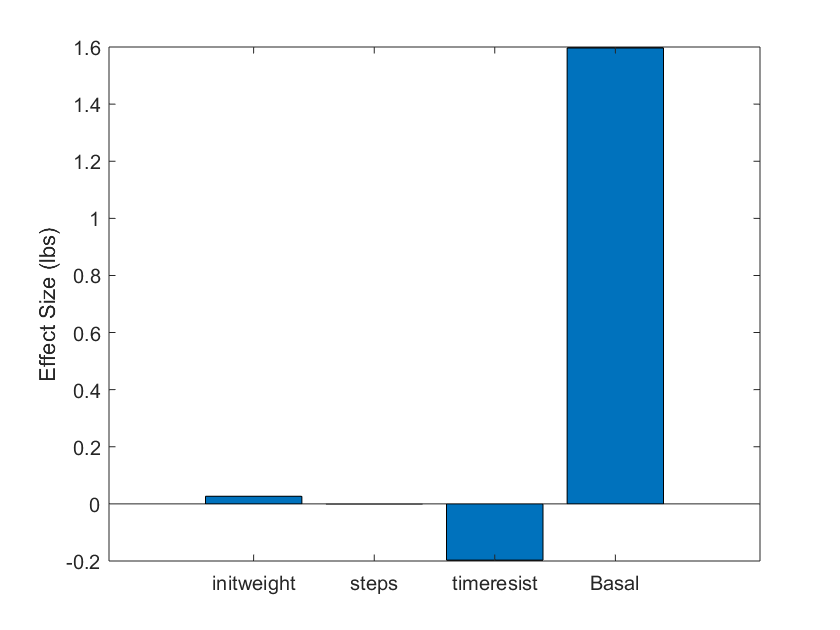


figure;
bar(w)
ylabel('Effect Size (lbs)')
set(gca, 'xticklabel', {'initweight', 'steps', 'timeresist', 'Basal'})

% show the coefficients again, so we can use the values in the caption.
w

w =     0.0268
   -0.0007
   -0.1969
    1.5963


**Figure Caption:** These are the "effect sizes" each column represents the amount feature is expected to change the result. The constant that we appended represents the average value removing the effect of the other features. In general, you want to use your "domain" knowledge to convert between the units used in the regression into ones that are more domain-specific. You would read it as such:

- The basal change in weight was an increase of 1.59 lbs.

- On average patients gained an extra 0.26 lbs for every 10 lbs of initial weight.  The unit in the database is per pound.

- Patients lost an average of 0.7 lbs for each 1000 step increment in their daily average.

- Patients lost an average of 1.97 lbs for each 10 minute increase in their daily average of resistance training.

**However, the above conclusion is biased.  Because the dbdata.initweight, dbdata.steps, and dbdata.timeresist have different normal distributions.  they differ in means and standard deviation.  To have a fair comparison, you need to normalize them before comparison. **

## Z scaling: (Normalization)

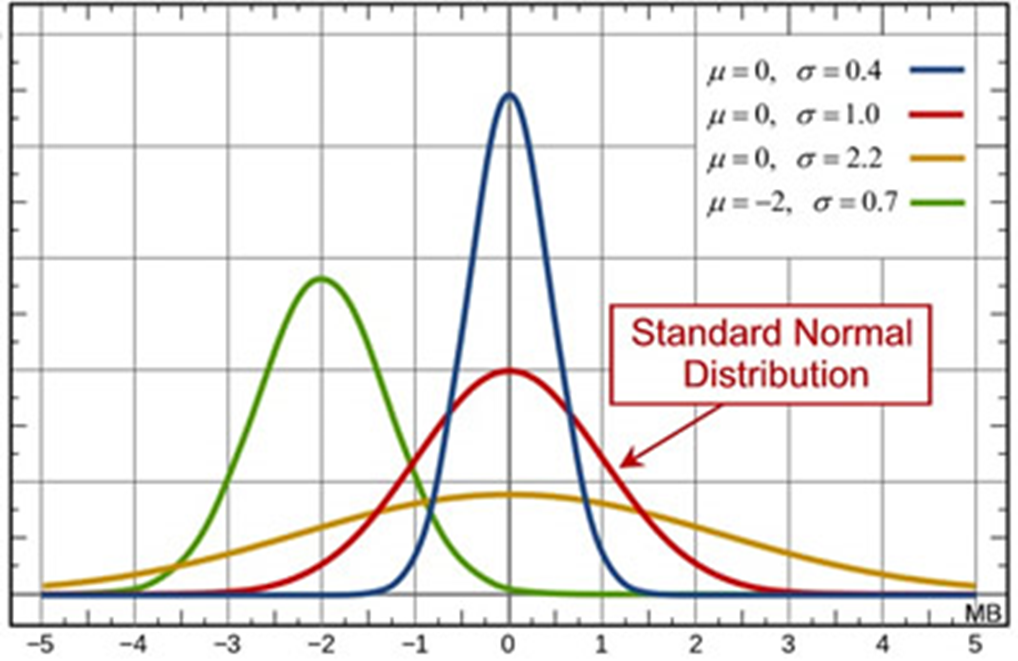


$$X_{\mathrm{normalized}} =\frac{X-\mu }{\sigma }$$


centers = mean(X,1)

centers = 	1.0e+03 *

    0.1615    3.5286    0.0181    0.0010


scales = std(X, [], 1)

scales =    29.1976  730.3464   18.1222         0



Xcenter = bsxfun(@minus, X, centers);
zX = bsxfun(@rdivide, Xcenter, scales);
zX(:, end) = 1

zX =    -0.8345   -0.2967   -0.8024    1.0000
   -0.2231    0.2262   -0.9286    1.0000
   -1.0090   -0.4586   -0.9694    1.0000
   -1.0860   -0.8034   -0.4945    1.0000
   -1.0015    0.1603   -0.9620    1.0000
    0.9053   -0.0033    1.1264    1.0000
   -0.2782    1.0325   -0.9964    1.0000
   -1.0369   -0.7306   -0.6047    1.0000
    2.0807   -1.3456    0.9613    1.0000
   -0.5801   -1.2486   -0.9449    1.0000


## Data Normalization

This presentation of the data is useful for presentation but it makes it difficult to interpret the "importance" of each feature since they're all on different scales. To fix this, we'll use a process call z-scaling. The idea is that we move all of them so they have a mean of 0 and a std of 1.

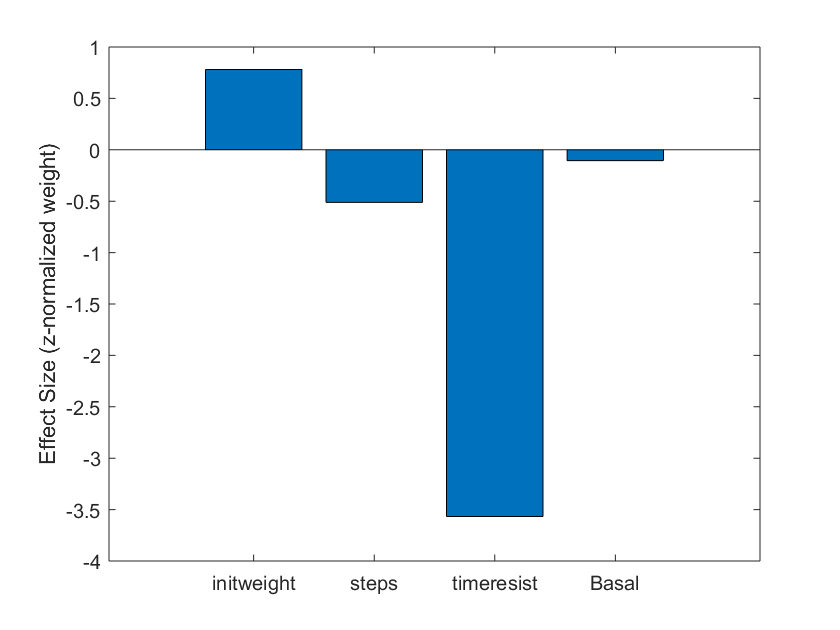

centers = mean(X,1);
scales = std(X, [], 1);
Xcenter = bsxfun(@minus, X, centers);
zX = bsxfun(@rdivide, Xcenter, scales);
zX(:, end) = 1; % reassign last column to 1. 

zw = mvregress(zX, y);


figure;
bar(zw)
ylabel('Effect Size (z-normalized weight)')
set(gca, 'xticklabel', {'initweight', 'steps', 'timeresist', 'Basal'})

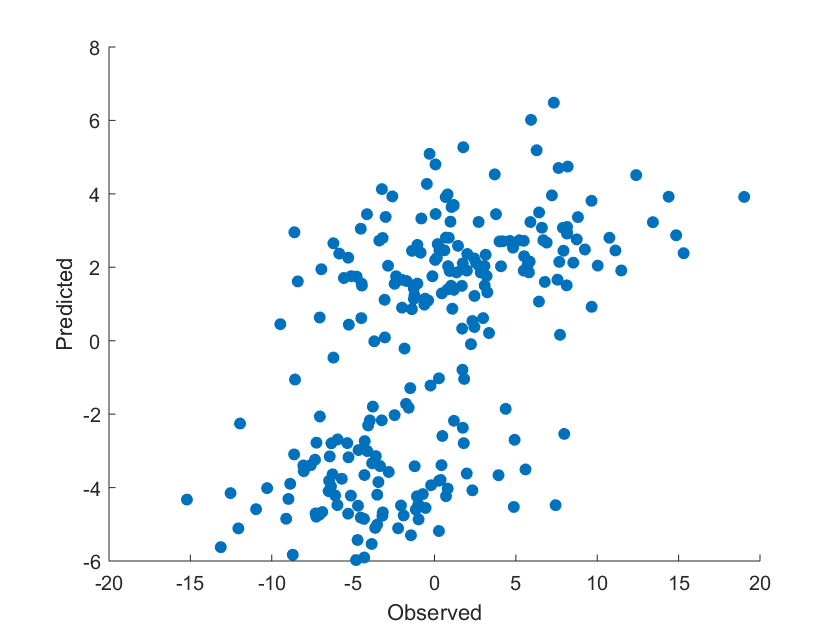


% Now that all of the variables are on the same scale, we can compare them.
% The timeresist has the greatest effect on the outcome.

% The other reason to do a z-scaled model is that it can bring out other
% important revelations
zpred = zX*zw;


figure;
scatter(y, zpred, 'filled')
xlabel('Observed'), ylabel('Predicted')

See how there are two clear groups. Lets use color to see which points correspond to which gender, and whether the groups coincide with gender.

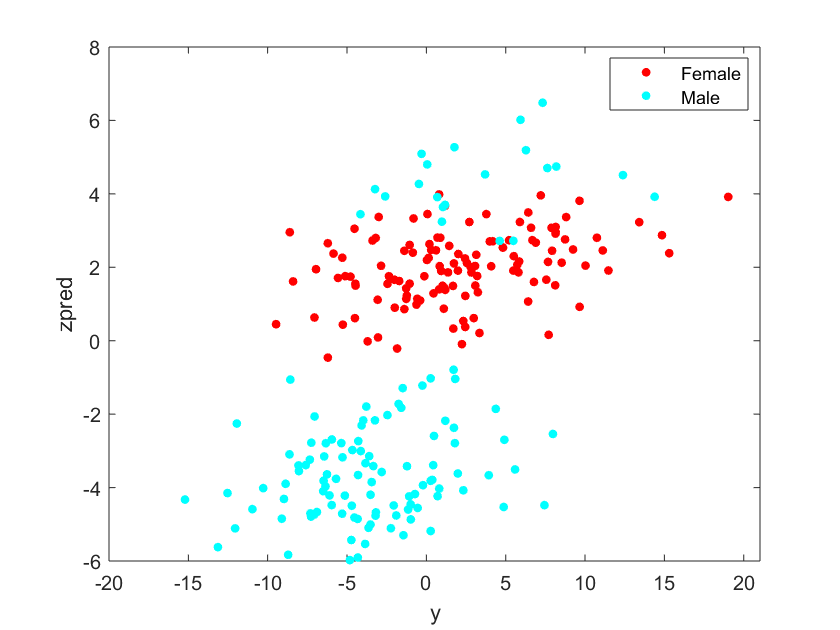

gscatter(y, zpred, dbdata.gender)

## Improving the model

Something that looks like this (a clear separation across another variable) indicates that  something is missing from our model. We really should have included it in our model. We need to encode gender numerically, let's use 0 for females and 1 for males.

xgender = double(strcmp(dbdata.gender, 'Male'));
X = [dbdata.initweight, dbdata.steps, dbdata.timeresist, ...
	xgender, ones(size(dbdata.timeresist))];
y = dbdata.deltaweight;

w = mvregress(X, y)

w =     0.0350
   -0.0007
   -0.1869
   -0.8340
    0.3582


ypred = X*w;

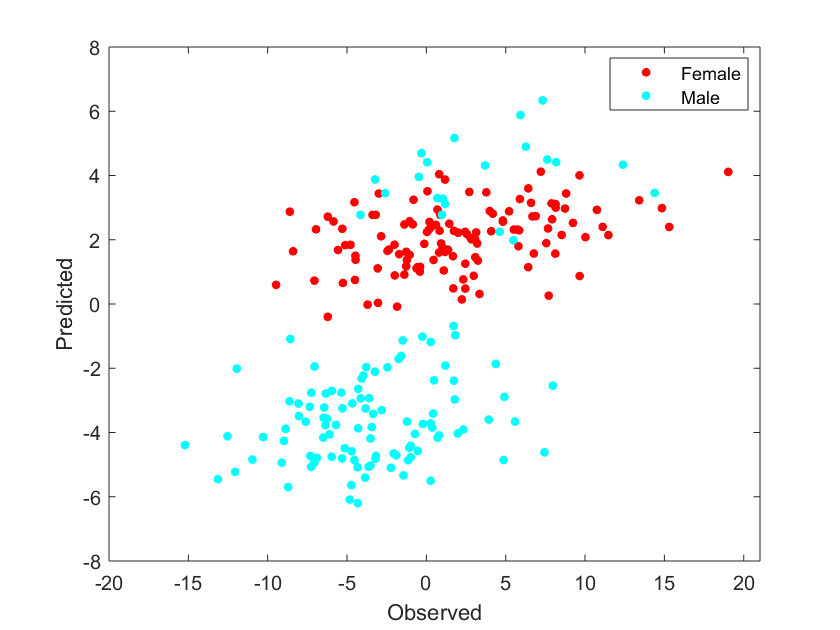


figure;
gscatter(y, ypred, dbdata.gender)
xlabel('Observed'), ylabel('Predicted')



[r, p] = corrcoef([y, ypred])

r =     1.0000    0.5609
    0.5609    1.0000


p =     1.0000    0.0000
    0.0000    1.0000



r2 = r(1,2)^2

r2 = 0.3146


h = p(1,2) < 0.01

h = logical
   1




% Now we can see that the predictions are better.

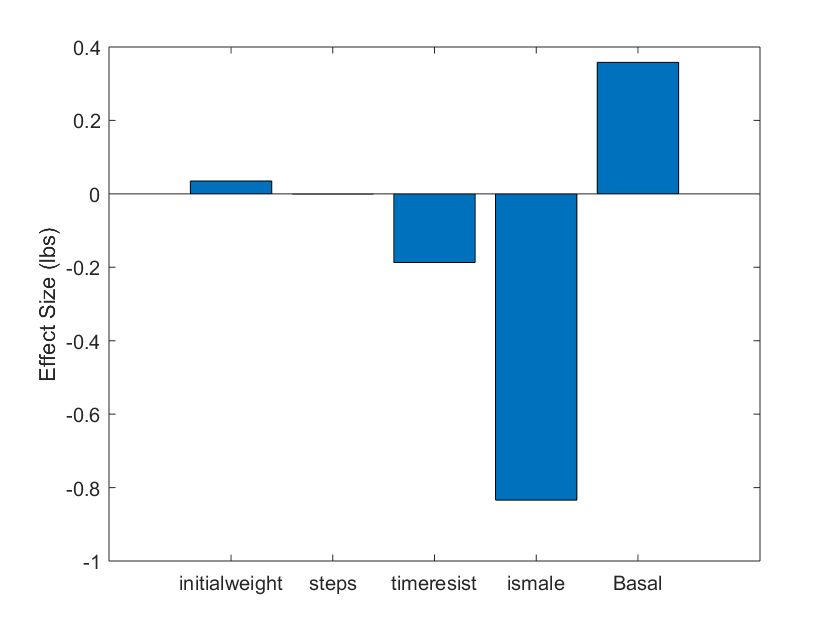


figure;
bar(w)
ylabel('Effect Size (lbs)')
set(gca, 'xticklabel', {'initialweight', 'steps', 'timeresist', 'ismale','Basal'})

**Figure Caption:** When we explain our effect sizes we need to be careful. Our "basal" is now the average FEMALE (the zero in our dummy variable). You would read it as such:

- Women on average had a basal change of 0.4 lbs while men on average had a basal change of -0.48 lbs (basal + ismale).

- If you did this with Males as zero, you would get THE SAME RESULT. The effect sizes would be reversed but the answer would be the same.

By including new terms, the other effect sizes have changed.

- On average patients gained an extra 0.35 lbs for every 10 lbs of initial weight.

- Patients lost an average of 0.7 lbs for each 1000 step increment in their daily average.

- Patients lost an average of 1.87 lbs for each 20-minute increase in their daily average of resistance training.

## Some caveats for this analysis.

- It is sensitive to non-linearities.

- When you add or remove features there may be many changes.

- It is sensitive to over-fitting. (Something we'll cover more in the future.)

- It is sensitive to inter-correlations within the features. For example, men (on average) do more resistance training than women (you can make the figure to prove it to yourself) and as such, these confuse the model. Ideally, you want to use features that are correlated with the output but not correlated with each other.